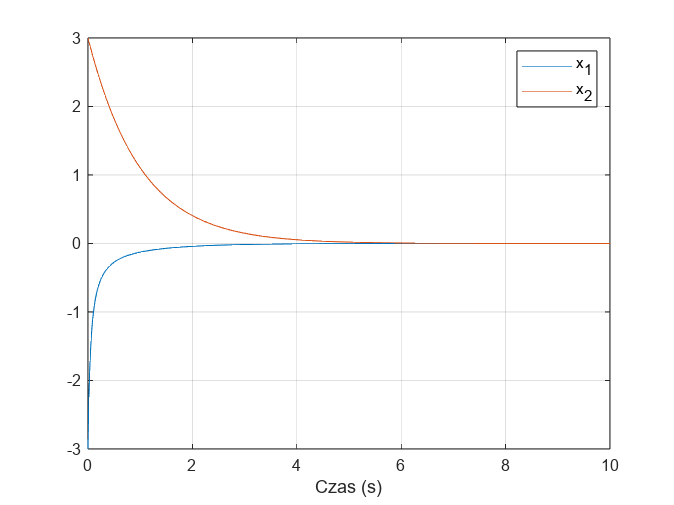

close all, clear all
%% System 41

%Simulation
tmax = 100;
x0 = [-3, 3];
[t_resp,x_resp] = ode45(@(t,x) system41(t,x),[0 tmax],x0');
figure;
plot(t_resp, x_resp(:,1), t_resp, x_resp(:,2)), xlim([0 10]),
xlabel('Czas (s)'), legend('x_1','x_2'), grid on

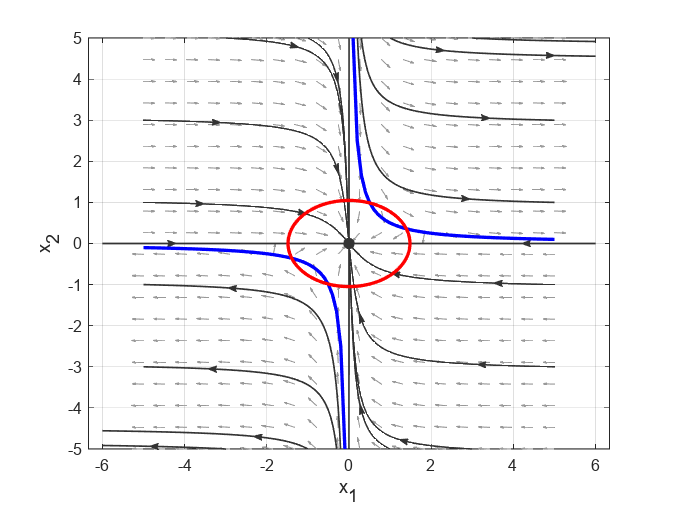


%Initial Phase Portrait
plotpp(@(t,x) [-x(1)+2*x(1)^2*x(2);-x(2)]), hold all
xlabel('x_1'), ylabel('x_2')
xlim([-5 5]), ylim([-5 5])
axis equal

%Approx Analytical Condition
plot([-5:0.1:5],1./(2*[-5:0.1:5]),'b','LineWidth',2)
%Select L for La Salle
l = 1.1;

%Plot ellipse as function of L
theta = linspace(0,2*pi) ;
% Ellipse equation: x1^2/a^2+x_2^2/b^2 = 1
% We have x1^2/2 + x2^2 = L
a = sqrt(2*l) ; b = sqrt(l) ;
x_ellipse = a*cos(theta) ;
y_ellipse = b*sin(theta) ;
plot(x_ellipse,y_ellipse,'r','LineWidth',2)

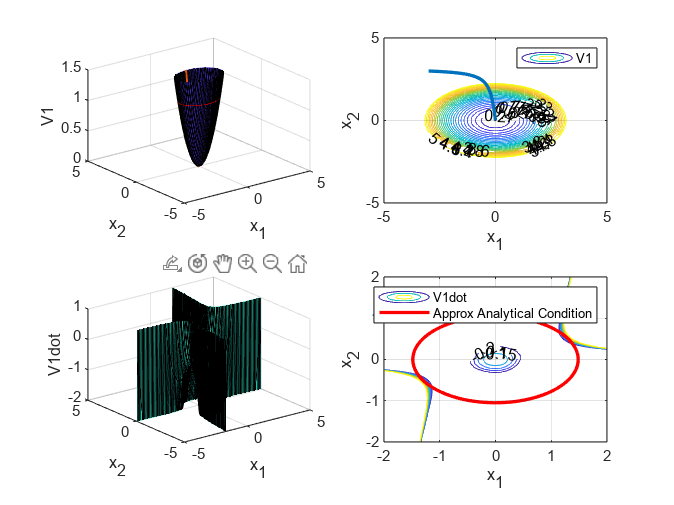


% Analyze Lyapunov Functional and its derivative
% Set up a meshgrid
x1 = [-5:0.1:5];
x2 = [-5:0.1:5];
[X1,X2] = meshgrid(x1,x2);

figure;
subplot(2,2,1)
% Visualize Lyapunov functional as a surface
% Calcute functional over mesh
V1 = X1.^2/2+X2.^2;
% Calculate functional for trajectory
V1_resp = x_resp(:,1).^2/2+x_resp(:,2).^2;
surf(X1, X2, V1); hold all
% Visualize Lyapunov functional with value L
plot3(x_ellipse,y_ellipse,l*ones(length(x_ellipse),1),'r')
% Visualize value of Lyapunov functional along the example of trajectory 
plot3(x_resp(:,1),x_resp(:,2),V1_resp,'LineWidth',2)
xlabel('x_1')
ylabel('x_2')
zlabel('V1')
zlim([0 1.5]);

subplot(2,2,2)
% Visualize Lyapunov functional as a contour
[C,h] = contour(X1, X2, V1, [-5:0.2:5]);
clabel(C,h);
xlabel('x_1'), ylabel('x_2'), grid on, hold all
% Display trajectory traversing contours
plot(x_resp(:,1),x_resp(:,2),'LineWidth',2)
legend('V1')

subplot(2,2,3)
% Visualize derivative of Lyapunov functional along trajectories as surface
% Calcute derivative of Lyapunov functional over mesh
V1dot = X1.*(-X1+2.*X1.^2.*X2)+2*X2.*(-X2);
% Calculate derivative of Lyapunov functional for trajectory
V1dot_resp = x_resp(:,1).*(-x_resp(:,1)+2.*x_resp(:,1).^2.*x_resp(:,2))+2*x_resp(:,2).*(-x_resp(:,2));  
surf(X1, X2, V1dot);
xlabel('x_1'), ylabel('x_2'), zlabel('V1dot')
zlim([-2, 1])

subplot(2,2,4)
% Visualize derivative of Lyapunov functional along trajectories as contour
[C,h] = contour(X1, X2, V1dot,[-0.2:0.05:0.2]);
clabel(C,h), hold all;
% Visualize approx analytical condition
% plot([-2:0.01:2],1./(2*[-2:0.01:2]),'LineWidth',2)
xlim([-2 2]), ylim([-2 2]);

% Visualize ellipse
plot(x_ellipse,y_ellipse,'r','LineWidth',2)
xlabel('x_1'), ylabel('x_2'), grid on
legend('V1dot','Approx Analytical Condition','Max Ellipse')

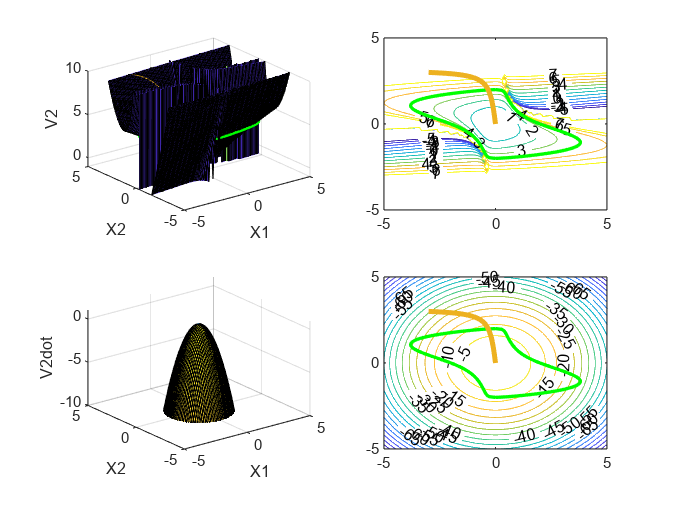


%% Select L maximising the ellipse as a region of attraction
%% Play with the figures and consider what you see:
% in particular derivative along trajectories
% what is the point of La Salle
% can we find a bigger region of attraction?

%% Let's try a more sophisticated functional that will make a derivative more pleasant
%% i.e. repeat analysis for V2

figure;
% Calcute functional over mesh
V2 = X1.^2./(1-X1.*X2)+X2.^2;
% Calculate functional for trajectory
V2_resp = x_resp(:,1).^2./(1-x_resp(:,1).*x_resp(:,2))+x_resp(:,2).^2;
% La Salle
% Select L for La Salle
l = 4;
% Calculate border for a given L
x2_plot = linspace(-2,2); hold all
x_a = (x2_plot.^3-l*x2_plot+sqrt((x2_plot.^3-l*x2_plot).^2-4*(x2_plot.^2-l)))/2;
x_b = (x2_plot.^3-l*x2_plot-sqrt((x2_plot.^3-l*x2_plot).^2-4*(x2_plot.^2-l)))/2;

subplot(2,2,1)
% Visualize Lyapunov functional as a surface
surf(X1, X2, V2); hold all
% Visualize Lyapunov functional with value L
plot3(x_a,x2_plot,l*ones(length(x_a),1),'g', 'LineWidth',3);
plot3(x_b,x2_plot,l*ones(length(x_b),1),'g', 'LineWidth',3);
% Visualiza Lyapunov functional values for a trajectory
plot3(x_resp(:,1),x_resp(:,2),V2_resp);
xlabel('X1')
ylabel('X2')
zlabel('V2')
zlim([-1 10])

subplot(2,2,2)
% Visualize Lyapunov functional as a surface
[C,h] = contour(X1, X2, V2,[-5:1:7]);
clabel(C,h);
x2_plot = linspace(-2,2); hold all
% Visualize La Salle region for L
plot(x_a,x2_plot,'g','LineWidth',2)
plot(x_b,x2_plot,'g','LineWidth',2)
plot(x_resp(:,1),x_resp(:,2),'LineWidth',3);

subplot(2,2,3)
% Visualize derivative of Lyapunov functional along trajectories as surface
% Calcute derivative of Lyapunov functional over mesh
V2dot = -2*X1.^2-2*X2.^2;
surf(X1, X2, V2dot);
xlabel('X1');
ylabel('X2');
zlabel('V2dot');
zlim([-10 1])
hold all
% Calcute derivative of Lyapunov functional for trajectory
V2dot_resp = -2*x_resp(:,1).^2-2*x_resp(:,2).^2;
plot3(x_resp(:,1),x_resp(:,2),V2dot_resp);

subplot(2,2,4)
% [C,h] = contour(X1, X2, V1dot,[-5:0.2:5]);

[C,h] = contour(X1, X2, V2dot,[-100:5:0]);
clabel(C,h), hold all;
% Visualize La Salle region for L
plot(x_a,x2_plot,'g','LineWidth',2)
plot(x_b,x2_plot,'g','LineWidth',2)
% Visualize trajectory
plot(x_resp(:,1),x_resp(:,2),'LineWidth',3);

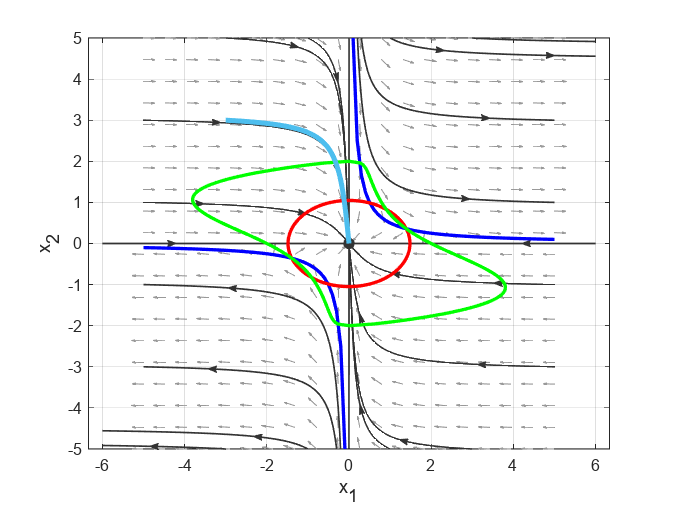


%% Finalize by displaying 3 regions on phase portrait (approx analytical, found with V1, found with V2)
%% Add initial condition outside of ellipse and approc analytical condition, but within region found using V2

plotpp(@(t,x) [-x(1)+2*x(1)^2*x(2);-x(2)]), hold all
xlabel('x_1'), ylabel('x_2')
xlim([-5 5]), ylim([-5 5])
axis equal

plot([-5:0.1:5],1./(2*[-5:0.1:5]),'b','LineWidth',2)
plot(x_ellipse,y_ellipse,'r','LineWidth',2)
plot(x_a,x2_plot,'g','LineWidth',2)
plot(x_b,x2_plot,'g','LineWidth',2)
plot(x_resp(:,1),x_resp(:,2),'LineWidth',3);

% procedura lapunowa, pośr i bezpośr, może na kartce coś, zaadoptować
% skrypt ten zeby coś przeanalizować, wyznaczanie stabilności i
% linearyzacja nieliniowych

## System 42

$$x = \left(\begin{array}{cc} x_{1} & x_{2} \end{array}\right)$$

$$V\_prim(t) = x_{1}\left(t\right)\,\frac{\partial }{\partial t}x_{1}\left(t\right)+x_{2}\left(t\right)\,\frac{\partial }{\partial t}x_{2}\left(t\right)$$

$$V\_prim(t) = -x_{1}\left(t\right)\,\left(x_{1}\left(t\right)-2\,{x_{1}\left(t\right)}^{2}\,x_{2}\left(t\right)\right)-{x_{2}\left(t\right)}^{2}$$